clear image
clear

Homography =     7.3460  -29.4495    3.8349   -5.8467
   13.5522  -25.9734    0.3210  -15.4455
    0.1622   -0.3543    0.0039   -0.1145


projection matrix for n = 6


Intrensic parameter matrix :


UpperTriangleMatrix =    -9.3465  -14.1535   76.6585
         0    3.8676   75.0895
         0         0    1.0000


Rotation Matrix : 


OrthogonalMatrix =    -0.0214    0.0012    0.9998
   -0.9089   -0.4165   -0.0190
   -0.4164    0.9091   -0.0100


translation =    -6.0750
    4.5433
    0.2939


FinalError = 26.3721

Homography =    -3.3551   22.4734   -1.4955   11.0865
  -10.0922   19.4209    0.9223   24.3531
   -0.1115    0.2530    0.0102    0.2240


projection matrix for n = 12


Intrensic parameter matrix :


UpperTriangleMatrix =    -6.4578  -22.2971   78.9632
         0    5.0768   79.0133
         0         0    1.0000


Rotation Matrix : 


OrthogonalMatrix =     0.0919    0.0005    0.9958
   -0.9105   -0.4048    0.0843
   -0.4032    0.9144    0.0368


translation =   -12.6565
    4.7360
    0.8097


FinalError = 23.2946

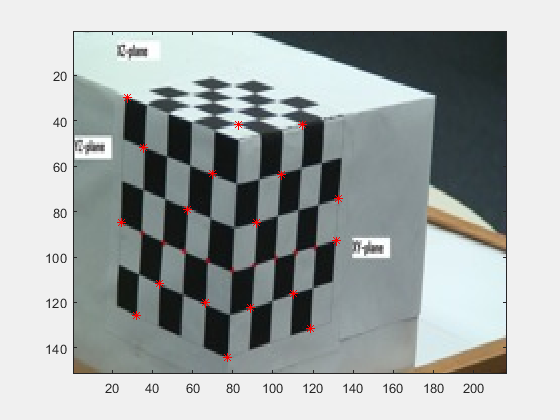

Homography =     1.3415   18.3619    0.7698   -1.3779
   -8.6191   18.3503    4.1727   14.5584
   -0.0959    0.2270    0.0462    0.0859


projection matrix for n = 18


Intrensic parameter matrix :


UpperTriangleMatrix =     5.7053  -34.1608   64.8350
         0    3.5035   82.4933
         0         0    1.0000


Rotation Matrix : 


OrthogonalMatrix =     0.4489    0.0076    0.8936
   -0.8076   -0.4245    0.4093
   -0.3825    0.9054    0.1844


translation =    46.0890
    8.5086
    0.3426


FinalError = 17.1881

% path for Q3 image
ImagePath = 'https://i.ibb.co/1mYxXW4/Q3-image.jpg';
[Img, Col]=imread(ImagePath); 
   
numberOfPoints = [6 12 18];

for n = 1:length(numberOfPoints)
    
    if(n == 1)
        XY3D1 = [0 2 3 1; 0 1 2 1; 4 2 0 1; 0 4 0 1; 1 2 0 1; 2 1 0 1];
    elseif(n == 2)       
        XY3D1 = [0 1 3 1; 0 2 3 1; 0 2 2 1; 0 4 1 1; 0 0 0 1; 2 0 1 1; 1 4 0 1; 2 2 0 1; 2 5 0 1; 4 1 0 1; 4 4 0 1; 5 2 0 1];        
    elseif(n == 3)
        XY3D1 = [0 0 5 1; 0 3 5 1; 0 1 4 0; 0 5 4 1; 0 4 3 1; 0 2 2 1; 0 1 1 1; 0 4 1 1; 1 0 1 1; 0 5 0 1; 1 2 0 1; 1 4 0 1; 2 1 0 1; 3 0 0 1; 3 4 0 1; 4 5 0 1; 5 2 0 1; 5 3 0 1]; 
    end
    
    % calculating 2D points
    XY2D=[];    
    image(Img); drawnow; hold on;
    for i=1:numberOfPoints(n)
        [x, y]=ginput(1);
        v=[x;y];
        plot(x, y, 'r*');
        set(gca, 'ydir', 'reverse')
        XY2D=[XY2D v];
    end
    
    % normalizing the points 
    MeanValues = mean(XY2D, 2);
    StandardDeviation = (2*std(transpose(XY2D)))/sqrt(2);
    normalizingMatrix = [(1/StandardDeviation(1)) 0 -MeanValues(1)/StandardDeviation(1); 0 (1/StandardDeviation(2)) -MeanValues(2)/StandardDeviation(2); 0 0 1];

    % normalizing the 3D points 
    XY3D = transpose(XY3D1);
    MeanValues3D = mean(XY3D, 2);
    StandardDeviation3D = (2*std(transpose(XY3D)))/sqrt(2);
    normalizingMatrix3D = [(1/StandardDeviation3D(1)) 0 0 -MeanValues3D(1)/StandardDeviation3D(1); 0 (1/StandardDeviation3D(2)) 0 -MeanValues3D(2)/StandardDeviation3D(2); 0 0 (1/StandardDeviation3D(3)) -MeanValues3D(3)/StandardDeviation3D(3); 0 0 0 1];
    % normalized points in real world 
    norxy3D = normalizingMatrix3D*XY3D;
    
    M = [];
    for j=1:numberOfPoints(n)
        temp = [XY2D(1,j); XY2D(2,j); 1];
        NorValues = normalizingMatrix*temp;
        
        r1 = [0 0 0 0 -norxy3D(1,j) -norxy3D(2,j) -norxy3D(3,j) -norxy3D(4,j) NorValues(2)*norxy3D(1,j) NorValues(2)*norxy3D(2,j) NorValues(2)*norxy3D(3,j) NorValues(2)*norxy3D(4,j)]; 
        r2 = [norxy3D(1,j) norxy3D(2,j) norxy3D(3,j) norxy3D(4,j) 0 0 0 0 -NorValues(1)*norxy3D(1,j) -NorValues(1)*norxy3D(2,j) -NorValues(1)*norxy3D(3,j) -NorValues(1)*norxy3D(4,j)];
        
        M = [M; r1; r2];
    end
    
    [U,S,V] = svd(M);
    M1 = V(:,end);    
    ProjectionMatrix = reshape(M1,[3,4]);
    
    % denormalizing to get homograpgy 
    Homography = inv(normalizingMatrix)*ProjectionMatrix*normalizingMatrix3D
      
    % removing the 4th column to get 3*3 matrix 
    text = ['projection matrix for n = ', num2str(numberOfPoints(n))];
    disp(text)
    PM = Homography(:,[1:end-1]);
        
    % RQ decomposition
    [Q,R] = qr(flipud(PM)');
    R = flipud(R');
    disp('Intrensic parameter matrix :')
    R = fliplr(R);
    UpperTriangleMatrix = (1/R(3,3))*R
    Q = Q';   
    disp('Rotation Matrix : ')
    OrthogonalMatrix = flipud(Q)
            
    % Calculating translation from last column of projection matrix
    Kt = Homography(:,end);
    translation = inv(R)*Kt
    
    % error     
    %ManualSelection=[35.0899 45.0438 55.9931 67.4401 79.3848 90.3341 101.7811 111.2373 120.1959; 88.7668 93.6093 97.5714 102.4140 106.3761 104.1749 101.5335 98.0117 95.8105];
    ManualSelection = [];  
    image(Img); drawnow; hold on;
    for i=1:9
    [x, y]=ginput(1);
    v=[x;y];
    plot(x, y, 'r*');
    ManualSelection=[ManualSelection v];
    end
      
    Error =[];
    tp1 = [0 3 4 1; 0 3 3 1; 0 3 2 1; 0 3 1 1; 0 3 0 1; 1 3 0 1; 2 3 0 1; 3 3 0 1; 4 3 0 1];
    tp = transpose(tp1);

    for j=1:9
        x = Homography*[tp(1,j);tp(2,j); tp(3,j); tp(4,j)];
        xdash = x(1)/x(3);
        ydash = x(2)/x(3);
        IndividualError = sqrt((ManualSelection(1,j)-xdash)^2 + (ManualSelection(2,j)-ydash)^2);
        Error = [Error IndividualError];
    end
    FinalError = sum(Error)/9    
end